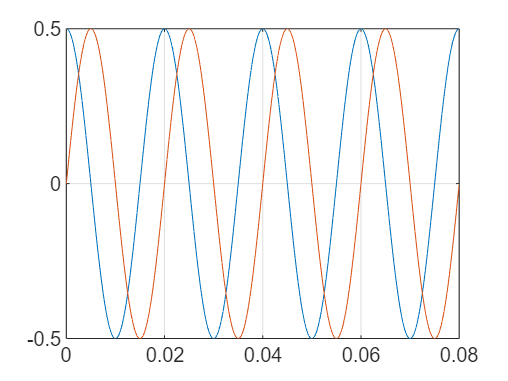

clear all
close all
clc
beep off


ts = 1e-4;
T = 20e-3;
time = [0:ts:4*T];
N = length(time);
theta = 2*pi/T*time;
ualpha = 0.5*cos(theta);
ubeta = 0.5*sin(theta);
figure; 
plot(time, ualpha, time, ubeta);
grid on


ua = zeros(1,N);
ub = zeros(1,N);
uc = zeros(1,N);
t0 = zeros(1,N);
t1 = zeros(1,N);
t2 = zeros(1,N);
sector_ref = zeros(1,N);
up = ones(1,N)*sqrt(3)/2;
% for i=1:N
% ua(i) = ualpha(i);
% ub(i) = (-1/2*ualpha(i) + sqrt(3)/2*ubeta(i));
% uc(i) = (-1/2*ualpha(i) - sqrt(3)/2*ubeta(i));
% end
% figure; 
% plot(time, ua, time, ub, time, uc);
% grid on


#### sector constraints

for i=1:N

    sector_ref(i) = (sign(ubeta(i)) - 2*sign(sqrt(3)/2*ualpha(i) - 0.5*ubeta(i)) + ...
        4*sign(-sqrt(3)/2*ualpha(i) - 0.5*ubeta(i)));

**sector1** : 

    if (sector_ref(i) == 3)
        t2(i) = ualpha(i) - ubeta(i)/sqrt(3);
        t1(i) = ubeta(i)*2/sqrt(3);
        t0(i) = up(i) - t2(i) - t1(i);
        uc(i) = t0(i)/2;
        ub(i) = t2(i) + uc(i);
        ua(i) = t1(i) + ub(i);
    end

**sector2** : 

    if (sector_ref(i) == 1)
        t2(i) = ualpha(i) + ubeta(i)/sqrt(3);
        t1(i) = -ualpha(i) + ubeta(i)/sqrt(3);
        t0(i) = up(i) - t2(i) - t1(i);
        uc(i) = t0(i)/2;
        ua(i) = t2(i) + uc(i);
        ub(i) = t1(i) + ua(i);
    end

sector3 : 

    if (sector_ref(i) == 5)
        t2(i) = ubeta(i)*2/sqrt(3);
        t1(i) = -ualpha(i) - ubeta(i)/sqrt(3);
        t0(i) = up(i) - t2(i) - t1(i);
        ua(i) = t0(i)/2;
        uc(i) = t2(i) + ua(i);
        ub(i) = t1(i) + uc(i);
    end

sector4 : 

    % section 4
    if (sector_ref(i) == 4)
        t2(i) = -ualpha(i) + 1/sqrt(3)*ubeta(i);
        t1(i) = -ubeta(i)*2/sqrt(3);
        t0(i) = up(i) - t2(i) - t1(i);
        ua(i) = t0(i)/2;
        ub(i) = t2(i) + ua(i);
        uc(i) = t1(i) + ub(i);
    end

sector5 : 

    % section 5
    if (sector_ref(i) == 6)
        t2(i) = -ualpha(i) - 1/sqrt(3)*ubeta(i);
        t1(i) = ualpha(i) - 1/sqrt(3)*ubeta(i);
        t0(i) = up(i) - t2(i) - t1(i);
        ub(i) = t0(i)/2;
        ua(i) = t2(i) + ub(i);
        uc(i) = t1(i) + ua(i);
    end

sector6 : 

    % section 6
    if (sector_ref(i) == 2)
        t2(i) = -2/sqrt(3)*ubeta(i);
        t1(i) = ualpha(i) + ubeta(i)/sqrt(3);
        t0(i) = up(i) - t2(i) - t1(i);
        ub(i) = t0(i)/2;
        uc(i) = t2(i) + ub(i);
        ua(i) = t1(i) + uc(i);
    end

end of sv

end

plot results

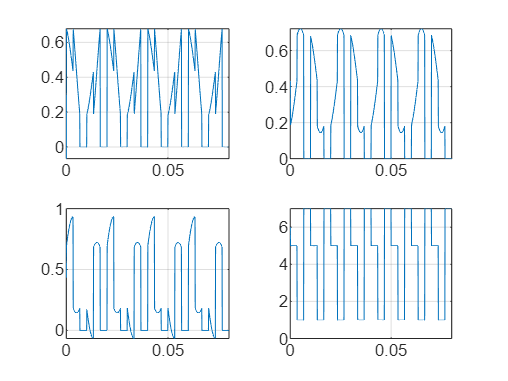

figure; 
subplot 221
plot(time, ua);
grid on
subplot 222
plot(time, ub);
grid on
subplot 223
plot(time, uc);
grid on
subplot 224
plot(time, sector_ref);
grid on